# Seminar 3

## PROBLEM 12

Data in Table 6 (also in file SM22_Seminar_3_Fish.xlsx) corresponds to an experiment carried out to compare 3 different methods to cook fish. For that purpose, 36 fish samples were randomly split in 3 groups of 12 samples. Samples in each group were cooked according to one of the methods, which we will call A, B, and C.

To compare the 3 methods, judges were asked to taste the cooked f fish samples and rate them in terms of 4 variables: Aroma, Flavor, Texture and Moisture. Table 6 provides these rates.

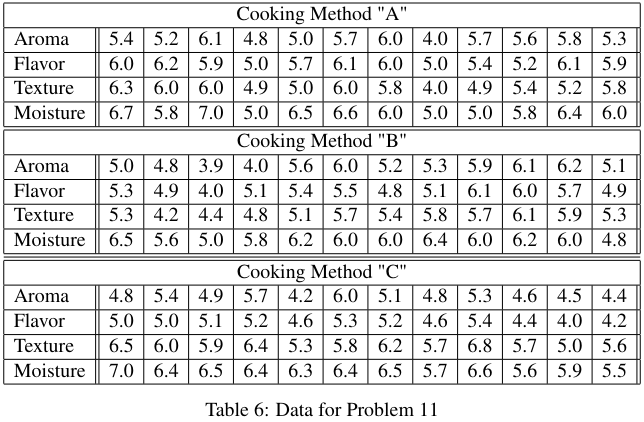

### a) State the null and alternative hypotheses required for the comparison indicated above.


$$\begin{cases}
      H_{0}: \mathbf{\mu_{l}} = \mathbf{\mu_{l\prime}} \quad \forall l, l\prime \in \{A, B, C\}\\
      H_{A}: \exists l \neq l\prime \quad \text{such that} \quad \mathbf{\mu_{l}} \neq \mathbf{\mu_{l\prime}}\\
\end{cases}$$


### b) Indicate what method would you use to test the hypotheses stated in (a). Indicate what assumptions would be needed in order for your method to be valid. For this problem, you do not need to test whether the assumptions hold; we will assume that they do.

I would use MANOVA. The assumptions are the following:

For each population $l$: $\mathbf{X}_{l,1}, \mathbf{X}_{l,2}, ..., \mathbf{X}_{l,n_{l}} \quad \forall l \in \{1, g\}$

- $\mathbf{X}_{l,1}, \mathbf{X}_{l,2}, ..., \mathbf{X}_{l,n_{l}} \quad \forall l \in \{1, g\}$ is a random sample of size $n_l$ from a population with mean $\mathbf{\mu_{l}}$. The random samples from different populations are independent.

- All populations have a common covariance matrix $\mathbf{\Sigma}$.

- All populations are multivariate normal or the sample size is large enough.

### c) Test the hypotheses stated in (a) at significance level α = 0.05. Provide all the relevant numerical details and clearly state your conclusion (both in terms of the null and in plain language).

alpha = 0.05;

% Importing table
filename = 'semi3/SM22_Seminar_3_Fish.xlsx';
% check that working directory is ME-2024
raw = readtable(filename, 'ReadVariableNames', false);
raw = strrep(raw{:,:}, ',', '.');

% Fill the input matrix
p = 4;
g = 3;
X = zeros(12, p, g); % n_l, p, g
X(:, :, 1) = str2double(raw(1:4, 3:14)');
X(:, :, 2) = str2double(raw(5:8, 3:14)');
X(:, :, 3) = str2double(raw(9:12, 3:14)');

% Compute the MANOVA table (treatment or between matrix B and residual or within matrix W)
X_bar = squeeze(mean(X, [1 3])); % p 1x4
n = repelem(size(X, 2), 3); % in this case all n_l are equal

% Compute Between Sum of squares and cross-products
df_B = g-1;
SSP_B = zeros(p, p);
for l=1:g
    SSP_B = SSP_B + n(l) * (X(:,:,l) - mean(X_bar))' * (X(:,:,l) - mean(X_bar)); % mean(X_bar) is the mean among populations, too
end

% Compute Within Sum of squares and cross-products
df_W = sum(n) - g;
SSP_W = zeros(p, p);
for l=1:g
    SSP_W = SSP_W + n(l) * (X(:,:,l) - X_bar)' * (X(:,:,l) - X_bar); % very similar but with individual population means
end

wilks_lambda = det(SSP_W) / det(SSP_B + SSP_W);

% Convert from from Wilk's Lambda distribution to F-distribution
s = min(p, df_B);
df_1 = p * df_B;
df_2 = s * (df_W - (p-df_B+1)/2) - p*df_B/2 + 1;

F_hat = ( (1 - nthroot(wilks_lambda, s)) / df_1 ) / ( nthroot(wilks_lambda, s) / df_2 )

F_hat = 7.0268

F_crit = finv(1-alpha, df_1, df_2)

F_crit = 2.8486

Since the estimator of the F-distribution exceeds the critical value we can reject the null hypothesis, that is, we can say that exists a combination of $l, l\prime$ such that $\mathbf{\mu_{l}} \neq \mathbf{\mu_{l\prime}}$.

### d) Compute 95% confidence regions for the average rating differences between the 3 cooking methods. These regions must hold at the specified confidence level simultaneously (e.g. do not forget to correct the significance level for multiple comparisons).

% Post-hoc multivariate test
m = g*(g-1) / 2; % correction 

% for t=1:m
%     X_bar
% end

## PROBLEM 13

File SM22_Seminar_3_Diet contains data from a study aimed to compare the effect of 3 different diets from a sample of 76 individuals. Each row of the file corresponds to one individual, and provides the gender, the type of diet (from 1 to 3) and two measurements of weight: one before starting the diet and another one after 6 weeks of diet. For the purpose of this problem we will assume that the data is suitable for analysis under a 2-way factorial ANOVA (i.e. the data fulfills all the assumptions required for such model), and we will use significance level α = 0.05:

### a) Test whether there is a significant interaction between (type of diet) and (gender). Clearly state:

- The corresponding null and alternative hypotheses

- Your conclusion

- The relevant numerical details

### b) Based on your results from (a), indicate whether further analysis of these data should be based on assessing main effects or simple effects. Justify adequately, including any additional analysis that you believe necessary to provide an adequate answer.

### c) Proceed to analyze main or simple effects, according to your answer in (b). In all cases provide your conclusions, clearly indicating what they imply stated in plain language.

### d) For any significant effect identified in (c), provide the corresponding confidence interval (keep in mind that, even though you are testing just a few selected intervals, you must correct the significance level for all possible multiple comparisons).

## PROBLEM 14

In one experiment involving remote sensing, the spectral reflectance of three species of 1-year-old seedlings was measured at various wavelengths during the growing season. The species of seedlings used were sitka spruce (SS), Japanese larch (JL), and lodgepole pine (LP). Files SM22_Seminar_3_Remote_??.xslx provides two of the variables that were measured:

- X1 = percent of spectral reflectance at wavelengt 560 nm (green)

- X2 = percent of spectral reflectance at wavelength 720 nm (near infrared)

where ?? are replaced by the abbreviations provided above for the 3 species of seedlings (SS, JL and LP).

### a) Test whether the mean reflectance (bi-dimensional, in terms of the two provided variables) is different between the 3 species of seedlings (at significance level α = 0.05). For the purpose of this question, consider that any required assumptions are met (no need to assert them).

### b1) In case you find a significant difference in (a), test what groups differ.

### b2) In case you do not find a significant difference in (a), construct confidence intervals for each pair of groups along each dimension. The intervals should simultaneously guarantee a FWER (family-wise error rate) of α = 0.05

### c) Assess whether the data fulfills the required assumptions for the test methodology that you applied in (a). Based on this, indicate whether you believe your results can be considered valid or not (justify).

## PROBLEM 15

In this problem we will analyze continuous evaluation data that corresponds to Statistical Models from 2019 to 2021. To this end, file SM_SamplesMarks_2019_2021.xlsx contains data from 78 students. For each of them (corresponding to a row in the referenced file), we have collected:

- The year in which the student took the course.

- The marks obtained in each of the 5 labs with deliverables.

- The resulting Continuous Evaluation mark (which is simply the average of the lab marks).

- The result of the student in the final exam, as a binary variable (1 = pass).

Students included in the file were selected randomly according to the following criteria:

- For each year, 13 students who passed the exam and 13 students who did not pass de exam were selected.

- Students with a Continuous Evaluation mark below 5.0 were not eligible, since they could not take the final exam.

We wish to assess whether, on average, there is a difference in the Continuous Evaluation mark of students depending on:

- Whether they successfully passed the final exam or not.

- The year in which they took the course. (This question is important because, in our case, the subject has both been updated every year and has changed some of its teachers)

Because we are using the same dataset for the 3 problems of this lab, we will set our significance level for each problem to α = 0.017, which is approximately 0.05/3.

### a) Indicate what method would you use to answer the research questions of this Problem. Indicate the assumptions that should be fulfilled (make sure to specify them clearly and adjusted to the data to be used; e.g. statements like "independence" without further clarification will not be accepted). For this problem, you do not need to test whether the assumptions hold; we will assume that they do.

### b) Test whether there is a significant interaction effect. Clearly state: 

- The corresponding null and alternative hypotheses

- Your conclusion

- The relevant numerical details

### c) Based on your results from (b), indicate whether further analysis of these data should be based on assessing main effects or simple effects. Justify adequately, including any additional analysis that you believe necessary to provide an adequate answer.

### d) Proceed to analyze main (In case of analyzing main effects, make sure to provide a complete analysis, e.g. including any post-hoc tests that might be necessary to determine what groups differ, if any) or simple effects, according to your answer in (c). In all cases provide your conclusions, clearly indicating what they imply for the two research questions proposed in this Problem.

## PROBLEM 16

Using data from Problem 15, we wish to assess whether, on average, there is a difference considering all the 5 Lab Marks of students (not simply their mean), depending on:

- Whether they passed the final exam or not.

- The year in which they took the course.

Because we are using the same dataset for the 3 problems of this lab, we will set our significance level for each problem to α = 0.017, which is approximately 0.05/3.

### a) Indicate what method would you use to answer the research questions of this Problem. Indicate the assumptions that should be fulfilled (make sure to specify them clearly and adjusted to the data to be used; e.g. statements like "independence" without further clarification will not be accepted). For this problem, you do not need to test whether the assumptions hold; we will assume that they do.

b) Test whether there is a significant interaction effect. Clearly state:

- The corresponding null and alternative hypotheses

- Your conclusion

- The relevant numerical details

### c) Based on your results from (a), indicate whether further analysis of these data should be based on assessing main effects or simple effects. Justify adequately, including any additional analysis that you believe necessary to provide an adequate answer.

### d) Proceed to analyze main (In case of analyzing main effects, make sure to provide a complete analysis, e.g. including any post-hoc tests that might be necessary to determine what groups differ, if any) or simple effects, according to your answer in (b). In all cases provide your conclusions, clearly indicating what they imply for the two research questions proposed in this Problem.